## Let's simulate some Lévy processes :

- Keep in mind that $$X_t = log(S_t/S_0)$$.

### I) Let's start with jump-diffusion :

We simulate here "jump diffusion" processes, which can be written as : $X_t = \mu t + \sigma W_t + \sum_{s\in[0, t)} \Delta X_s = \mu t + \sigma W_t +\sum_{i=1}^{N(t)} Y_i

$, $N
$ being a Poisson Process of intensity $\lambda
$ and $(Y_i)_i
$ i.i.d random variables.

#### I-1) Merton Model :

- 
$$Y_i \sim N(\mu_J, \delta_J^2)$$


- Defined by $(\sigma, \lambda, \mu_J, \delta_J)$

Process parameters :

S0 = 1;         % Initial value
mu = 0.05;      % Drift (as in GBM)
sigma = 0.4;    % Volatility (as in GBM)
lambda = 2;     % Poisson intensity/rate
muJ = 0.01;     % Jumpsize mean
deltaJ = 0.2;   % Jumpsize std

Simulation parameters :

T = 2;      % Maturity
M = 100;    % Number of steps in time
dt = T/M;   % Time step

**Conditional simulation of jump times** (the easiest way) :

(cf ALGORITHM 6.2 from Simulate_Jump_Diffusion.pdf)

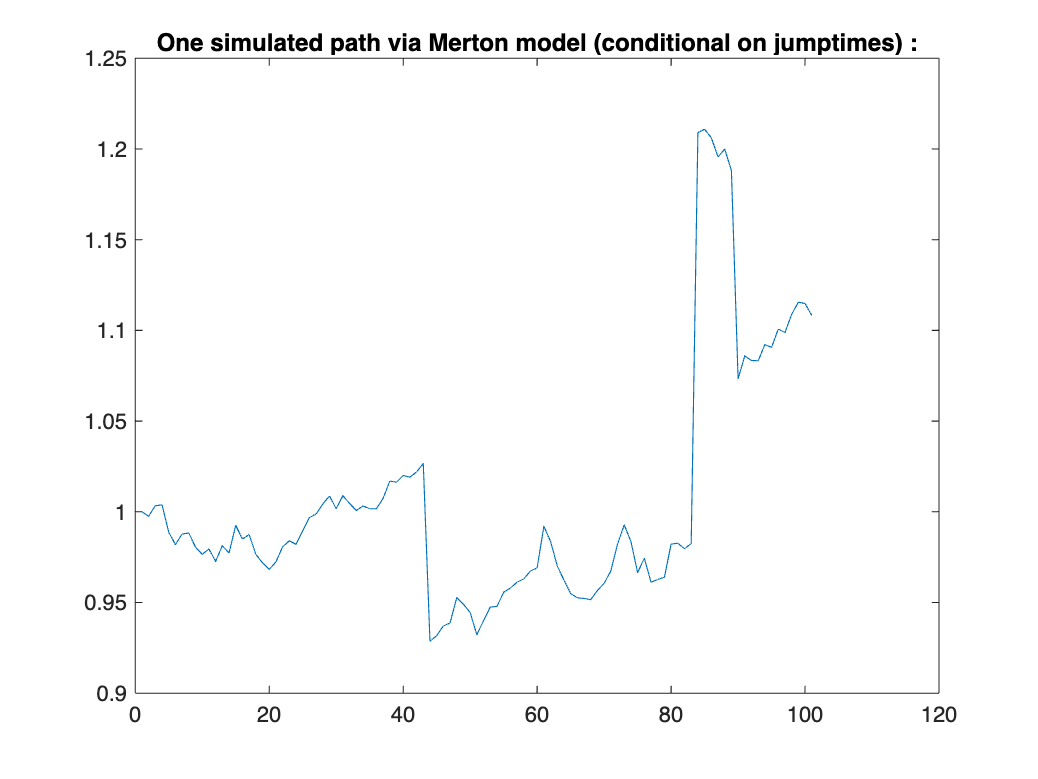

X = zeros(M + 1, 1); % X = (X0, X1, ..., XM)
Z = randn(M, 1);     % Z = (Z1, Z2, ..., ZM) [BM]

NT = poissrnd(lambda*T); % Nb of jumps in [0,T]

% Conditional to NT, we simulate when jumps occur
% via an Uniform Distribution :
jumpT = sort(rand(1,NT)*T);

% In Merton, jumpSize ~ Normal(muJ, deltaJ^2) :
jumpSize = muJ + deltaJ * randn(NT,1);
for i=1:M
    % Continuous part of the process :
    X(i+1) = X(i) + mu * dt + sigma * dt * Z(i);
    % Jump part :
    for j=1:NT
        % Did a jump occur in ](i-1)dt, idt] ?
        if jumpT(j) > (i-1)*dt && jumpT(j) <= i*dt
            X(i+1) = X(i+1) + jumpSize(j);
        end
    end
end
figure; % Plot
plot(S0 * exp(X));
title("One simulated path via Merton model (conditional on jumptimes) :")

**Another simulation of jump times** : (cf ALGO 6.1 from Simulate_Jump_Diffusion.pdf) we simulate jumps inside the loop, at each time step.

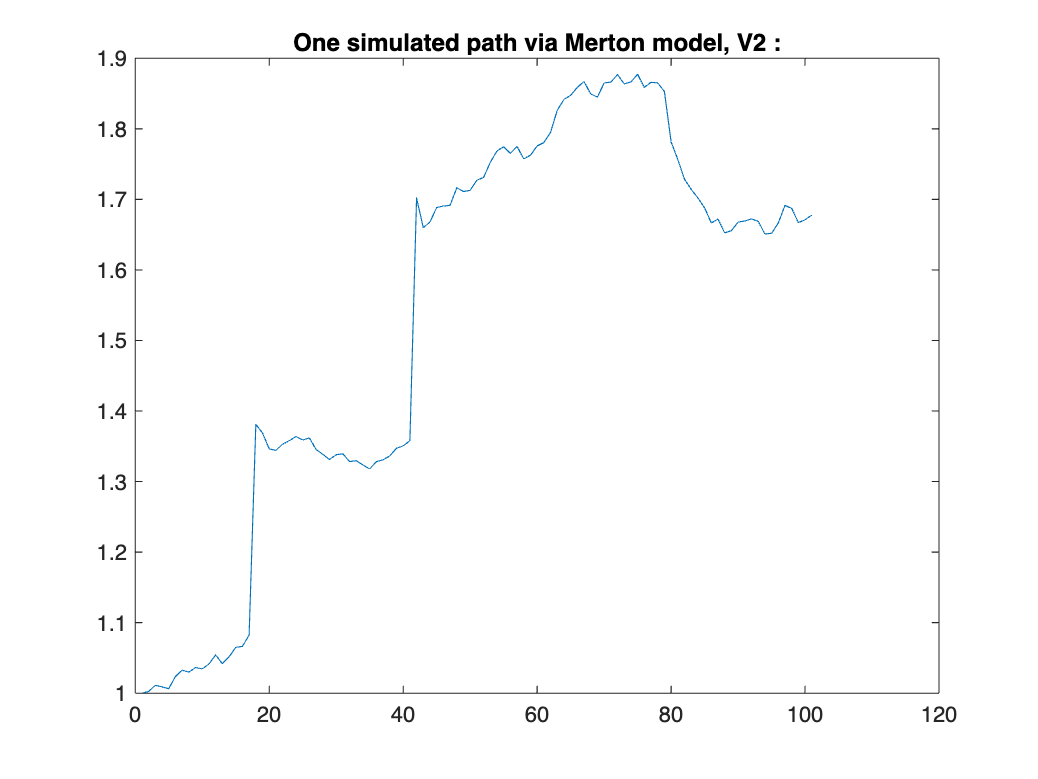

X = zeros(M + 1, 1); % X = (X0, X1, ..., XM)
Z = randn(M, 1);     % Z = (Z1, Z2, ..., ZM) [BM]

for i=1:M
    % Continuous part of the process :
    X(i+1) = X(i) + mu * dt + sigma * dt * Z(i);
    % Jump part :
    Ndt = poissrnd(lambda * dt);

    if Ndt == 0
        J = 0; % No jump !
    else 
        J = sum(muJ + deltaJ * randn(Ndt,1)); % Sum of the jump(s)
        % that happened during this time step.
    end
    X(i+1) = X(i+1) + J; % @ each time step : add the jump(s).
end
figure; % Plot
plot(S0 * exp(X));
title("One simulated path via Merton model, V2 :")

#### I-2) Kou Model :

- Positive jumpsize $\sim exp(\lambda^+)$ ;

- Negative jumpsize $\sim exp(\lambda^-)
$ ;

Process parameters :

S0 = 1;           % Initial value
mu = 0.05;        % Drift (as in GBM)
sigma = 0.4;      % Volatility (as in GBM)
lambda = 2;       % Poisson intensity/rate
p = 0.6;          % Probability of a positive jump
lambda_plus = 10; % Parameter of Exp() for POSITIVE jumps
lambda_minus = 3; % Parameter of Exp() for NEGATIVE jumps

Simulation parameters :

T = 2;      % Maturity
M = 100;    % Number of steps in time
dt = T/M;   % Time step

**Conditional simulation of jumptimes :** (cf ALGO 6.2)

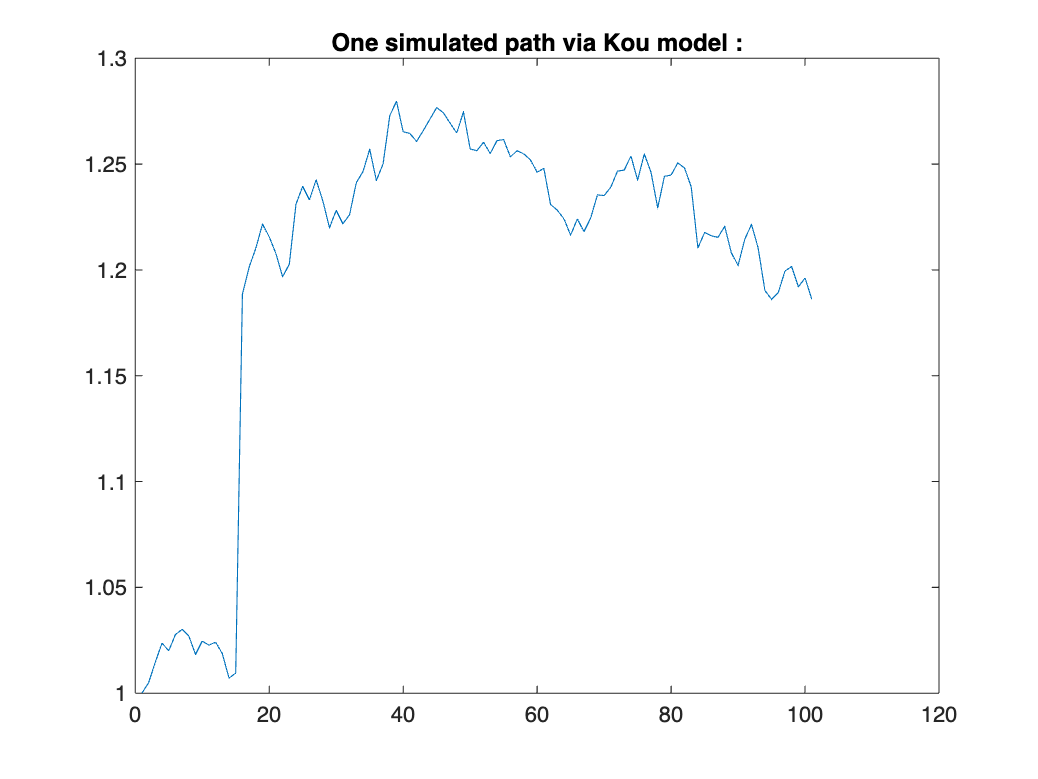

X = zeros(M + 1, 1); % X = (X0, X1, ..., XM)
Z = randn(M, 1);     % Z = (Z1, Z2, ..., ZM) [BM]

NT = poissrnd(lambda*T); % Nb of jumps in [0,T]

% Conditional to NT, we simulate when jumps occur
% via an Uniform Distribution :
jumpT = sort(rand(1,NT)*T);

% In Kou, jumpSize ~ Exp(lambda^+ or lambda^-) :
for i=1:M
    % Continuous part of the process :
    X(i+1) = X(i) + mu * dt + sigma * dt * Z(i);
    % Jump part :
    for j=1:NT
        % Did a jump occur in ](i-1)dt, idt] ?
        if jumpT(j) > (i-1)*dt && jumpT(j) <= i*dt
            % RV ~ U((0,1)) gives type of jump (+ or -) :
            u = rand; 
            if u < p % >0 jump
                jumpSize = exprnd(1/lambda_plus);
            else     % <0 jump
                jumpSize = -exprnd(1/lambda_minus);
            end
            % Add the simulated jumpsize :
            X(i+1) = X(i+1) + jumpSize;
        end
    end
end 
figure; % Plot
plot(S0 * exp(X));
title("One simulated path via Kou model :")